# Obtaining 2° order TF from 3° order Tustin

z = tf('z',0.05)

z =
 
  z
 
Sample time: 0.05 seconds
Discrete-time transfer function.
Model Properties


Gpz = 0.005208*z / (z^2 - 0.2774*z - 0.3987)

Gpz =
 
        0.005208 z
  -----------------------
  z^2 - 0.2774 z - 0.3987
 
Sample time: 0.05 seconds
Discrete-time transfer function.
Model Properties


Gz = Gpz * z

Gz =
 
       0.005208 z^2
  -----------------------
  z^2 - 0.2774 z - 0.3987
 
Sample time: 0.05 seconds
Discrete-time transfer function.
Model Properties


Gs = d2c(Gpz)

Gs =
 
     0.0896 s^2 + 7.624 s + 321.3
  -----------------------------------
  s^3 + 31.95 s^2 + 4263 s + 1.998e04
 
Continuous-time transfer function.
Model Properties


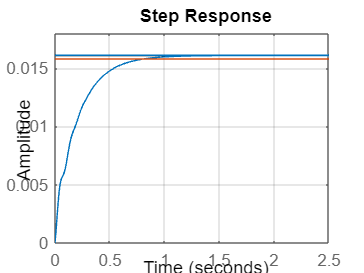

step(Gs)
hold on
grid on
t = [0:0.1:2.5];
sz = size(t,2);
plot(t,ones(sz,1).*0.0161);
plot(t,ones(sz,1).*0.0161*0.98);

tr = 0.804;
tp = 0.804;
ts = 0.804;
beta = 0;
sigma = 4/ts;
wd = tan(0)*sigma;
tp = 